## Ways of computing the singular value decomposition including explanations of inner workings.

According to [https://towardsdatascience.com/simple-svd-algorithms-13291ad2eef2](https://towardsdatascience.com/simple-svd-algorithms-13291ad2eef2)

clear all; close all; clc




SVD introduction: converts a matrix M into U, E and V*

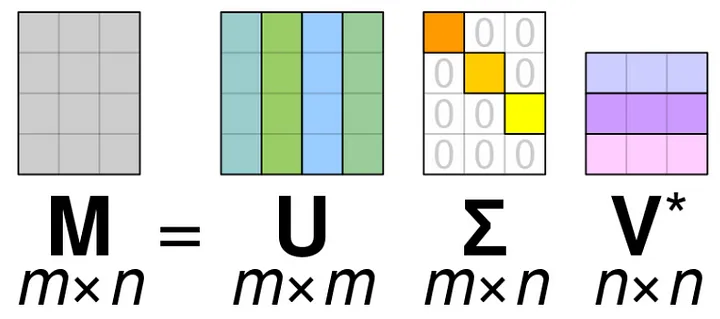

where

- M is the original matrix to decompose

- U is the left singular matrix (columns are left signular vectors), containing eigenvectors of matrix MM'

- E is a diagonal matrix containing singular (eigen)values

- V is the right singular matrix (columns are right singular vectors), containing eigenvectors of M'M

SVD is comparable to Principal Component Analysis (PCA), however SVD can handle matrices with different number of columns and rows (m ~= n).

A different visualization of the SVD:

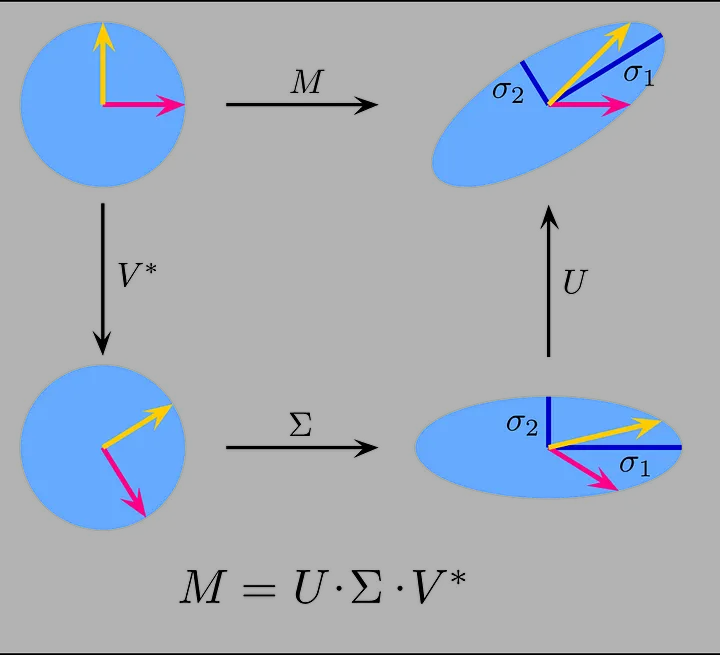

From this image is visible that the following steps are executed:

- change of basis from standard basis to the basis V (using V'). In this image shown as a simple rotation.

- transformation described by matrix E. In this example scaling the vector in basis V.

- change of the basis from V to basis U. 

### Example of computing the singular value decomposition of a given matrix

% Given input matrix
A = [1 2 3; 4 5 6; 7 8 9];

% Computing the transpose of A
A_trans = A';

% Compute the Gram matrix: A*A_trans
AtA = A*A_trans;

% Compute the covariance matrix: A_trans*A
AAt = A_trans*A;

% Compute the eigenvalues- and vectors of A*A_trans
[V1,D1] = eig(AtA);

% Compute the eigenvalues- and vectors of A_trans*A
[V2,D2] = eig(AAt);

% Extracting singular values. NOTE that D1 == D2
[sigma, ind] = sort(sqrt(diag(D1)),'descend');

% Computing the left and right singular vectors
U = V1(:,ind);
V = V2(:,ind);

% Compute the singular value matrix
S = diag(sigma);

% Check if A = U*S*V' (double check) with round on 6 decimals
round(A - U*S*V',6)

ans =      0     0     0
     0     0     0
     0     0     0



% Check if U is orthonormal (each column is linearly independent and has
% length of 1)
if (round(U'*U,12) == eye(3))
    disp('U is orthonormal')
else
    disp('U is NOT orthonormal')
end

U is orthonormal



% Check if V is orthonormal
if (round(V'*V,12) == eye(3))
    disp('V is orthonormal')
else
    disp('V is NOT orthonormal')
end

V is orthonormal
